# Impendance data present

측정된 Re Rct 로 그림을 그리는것이 잘 되지 않는다.

load ../B0005.mat


BAT1 =B0005;


%%%%%%%%%%%%%%% calculate ohm by Voltage and current 

items = size(BAT1.cycle,2)

items =    616


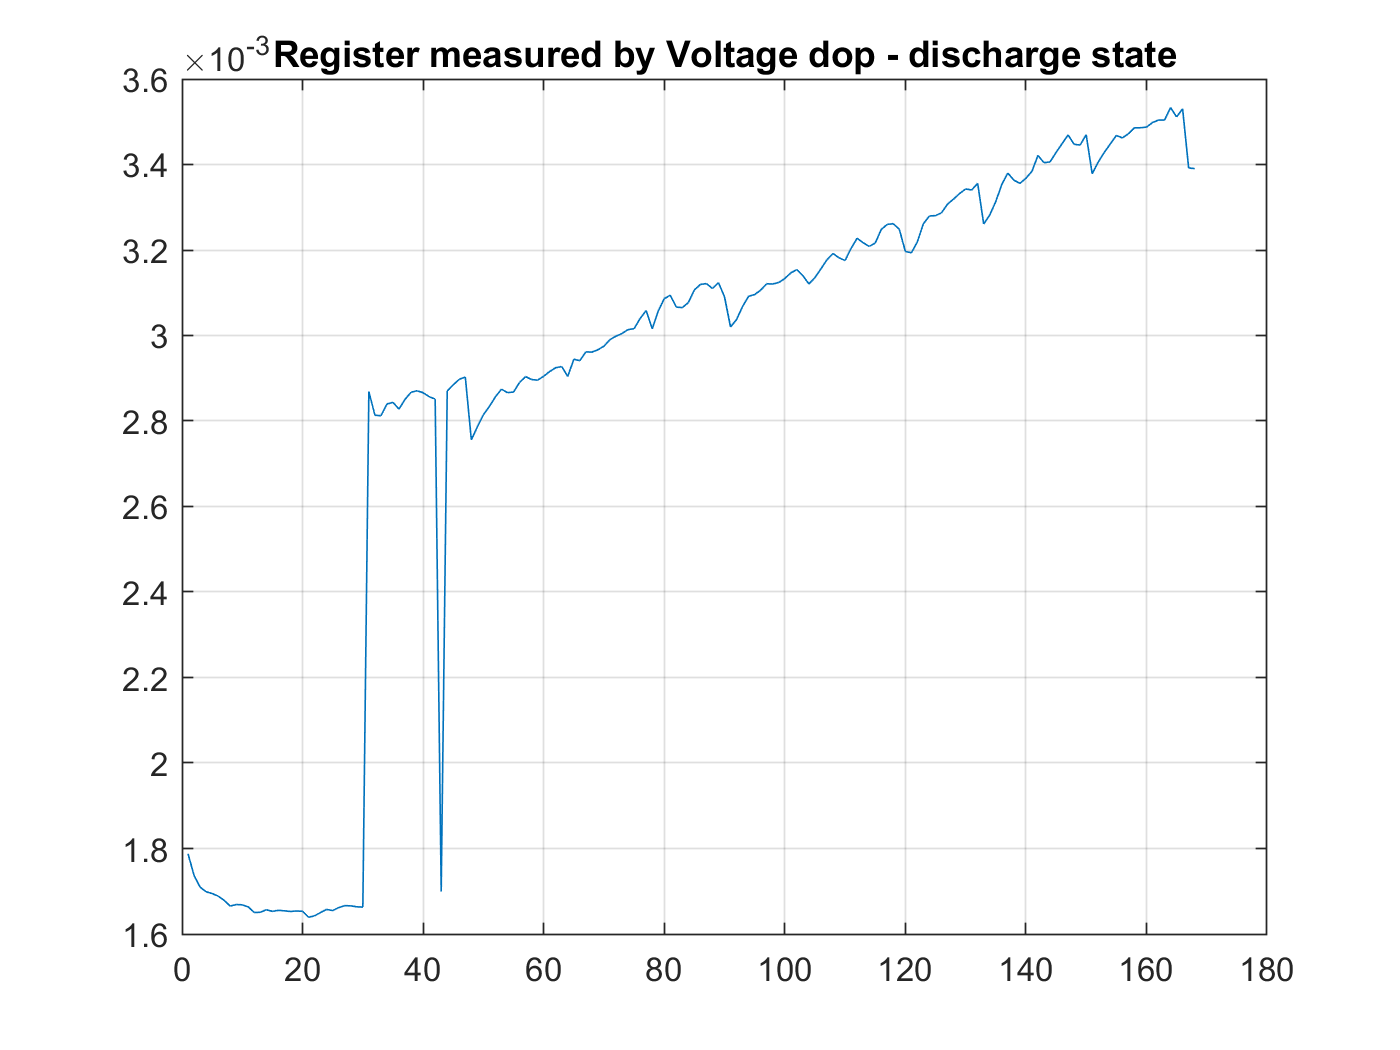

ohm_index=1;
deltaVoltages = [];
ohm = [];
Ifirst3 = 2; % 2A CC load
Vfirst3 = 4.2;
indexV = []; 
start_index = 1;
measure_index = 5;
for i=1:items
    if isequal(BAT1.cycle(i).type, 'discharge')
        deltaV = BAT1.cycle(i).data.Voltage_measured(start_index) -  BAT1.cycle(i).data.Voltage_measured(measure_index);
        deltaT = BAT1.cycle(i).data.Time(measure_index) - BAT1.cycle(i).data.Time(start_index);
        
        % deltaV = Vfirst3 -  BAT1.cycle(i).data.Voltage_measured(measure_index);
        % deltaT = BAT1.cycle(i).data.Time(measure_index) ;
        
        %BAT1.cycle(i).data.Voltage_measured(1)
        deltaVoltages(ohm_index) =  deltaV;
        ohm(ohm_index) = deltaV / (deltaT * Ifirst3 );
        indexV(ohm_index)=i;
        
        ohm_index=ohm_index+1;
    end
end

figure
plot(ohm)

title("Register measured by Voltage dop - discharge state")
% 앞부분이 이상한 데이타가 있다
grid on

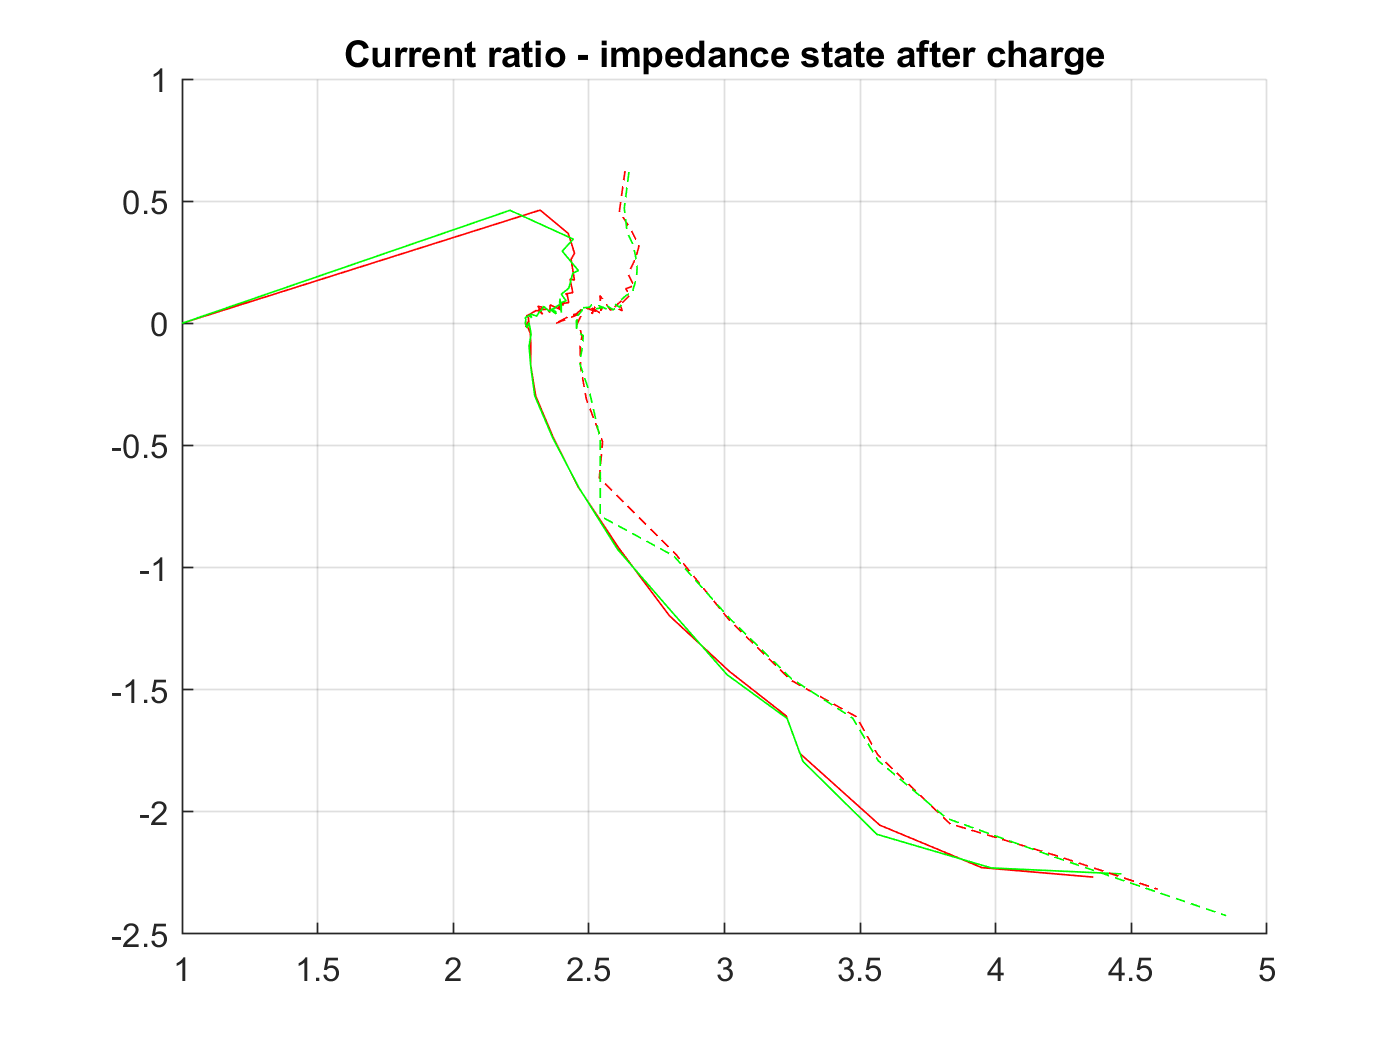


%%% Registor  Current_ratio

figure 
hold on
% after charge 
plot(BAT1.cycle(41).data.Current_ratio,'r-')
plot(BAT1.cycle(45).data.Current_ratio,'g-')
plot(BAT1.cycle(607).data.Current_ratio,'r--')
plot(BAT1.cycle(611).data.Current_ratio,'g--')
hold off
title("Current ratio - impedance state after charge")
grid on

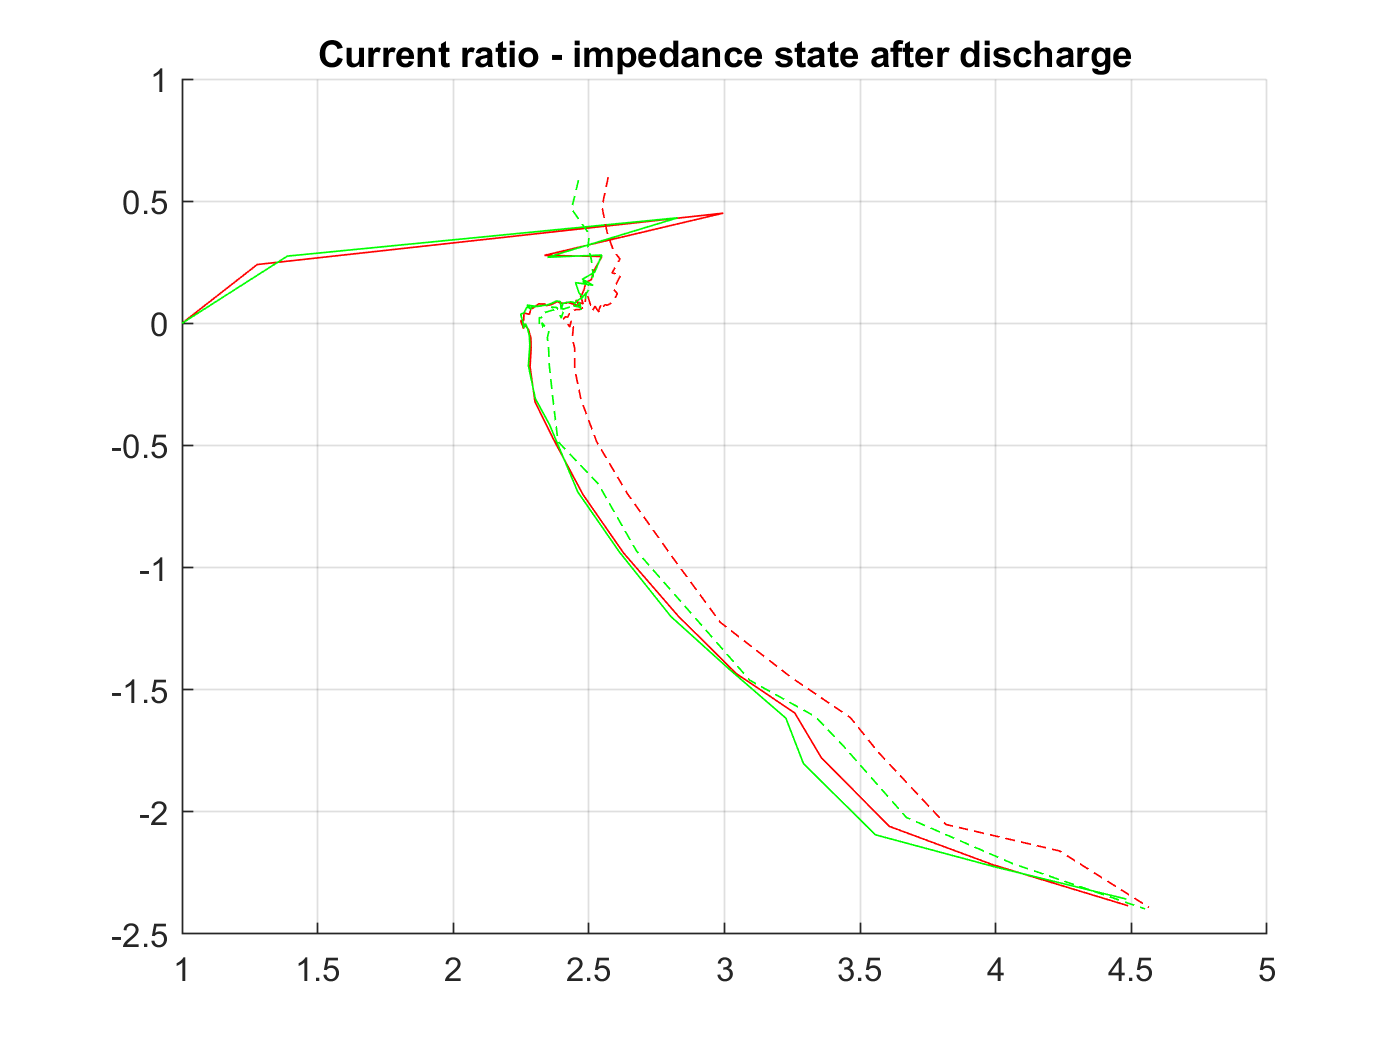


figure 
hold on
% after didscahage 43 47 
plot(BAT1.cycle(43).data.Current_ratio,'r-')
plot(BAT1.cycle(47).data.Current_ratio,'g-')
plot(BAT1.cycle(609).data.Current_ratio,'r--')
plot(BAT1.cycle(615).data.Current_ratio,'g--')
hold off
title("Current ratio - impedance state after discharge")
grid on

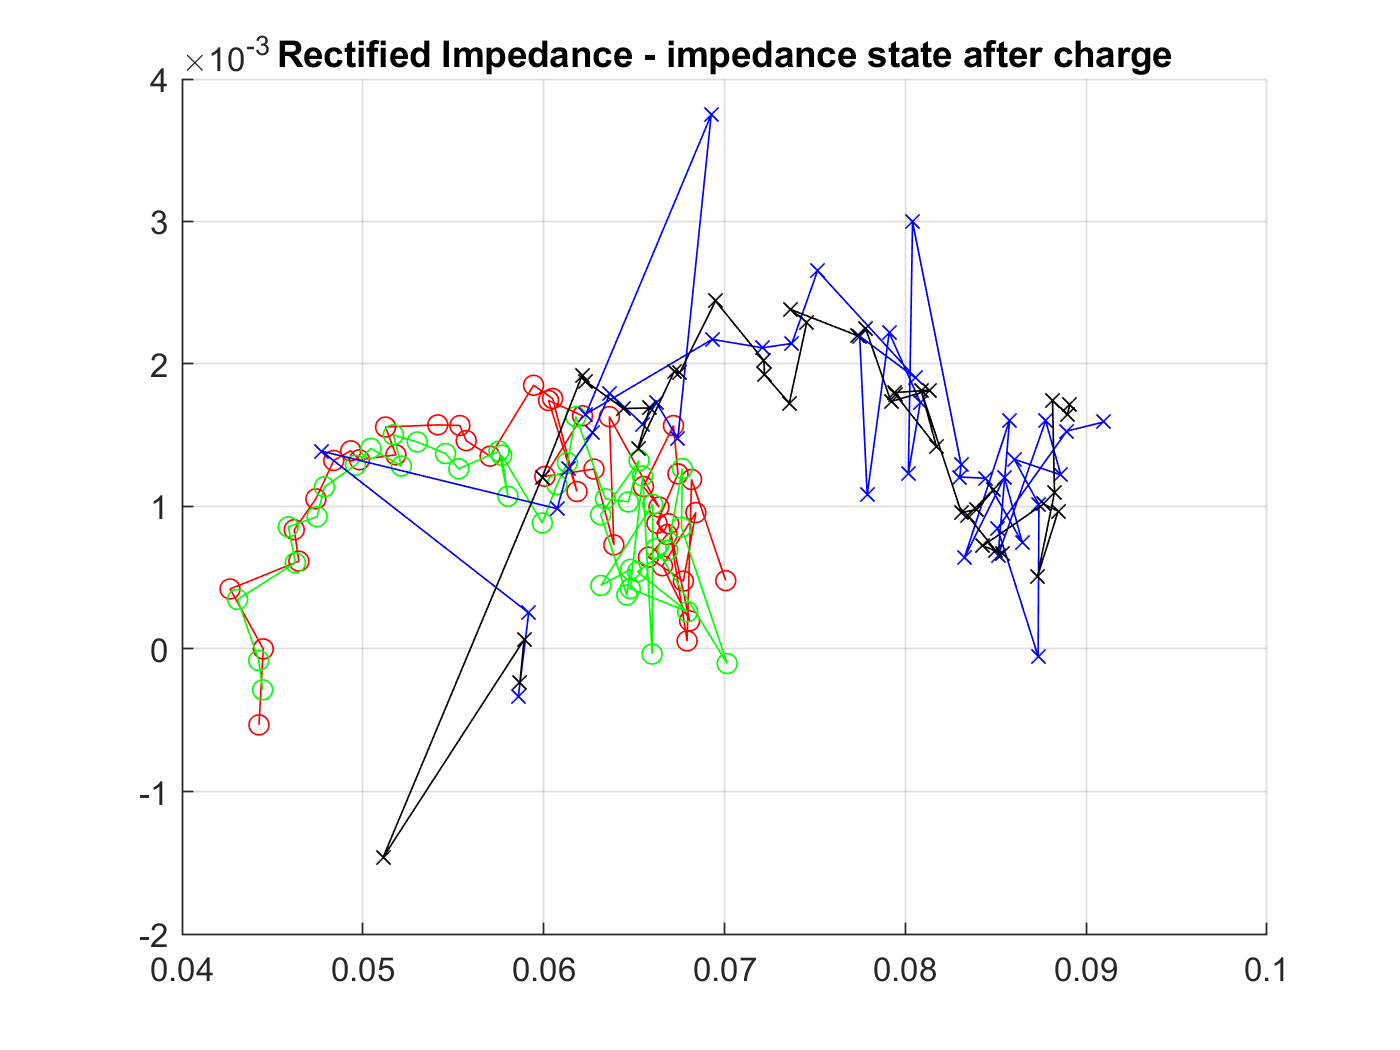



%%% Rectified Impedance
figure 
hold on
% after charge 
plot(BAT1.cycle(41).data.Rectified_Impedance','r-o')
plot(BAT1.cycle(45).data.Rectified_Impedance','g-o')
plot(BAT1.cycle(607).data.Rectified_Impedance','b-x')
plot(BAT1.cycle(611).data.Rectified_Impedance','k-x')
hold off
title("Rectified Impedance - impedance state after charge")
grid on

BAT1.cycle(43).data.Rectified_Impedance

ans =   0.060356658670812 - 0.000232316905666i
  0.078153690868441 - 0.001625896670506i
  0.074117048597969 - 0.001041994775756i
  0.073671498407839 - 0.000816694877807i
  0.072443229572905 - 0.001402168286671i
  0.072575593517905 - 0.001116441420560i
  0.073061886462496 - 0.000925010099553i
  0.071618247851838 - 0.001275091393569i
  0.072900630515852 - 0.000657934244539i
  0.070773816214409 - 0.001280054982339i


BAT1.cycle(43).data.Re

ans =    0.046687001624869


BAT1.cycle(43).data.Rct

ans =    0.076274740985306



BAT1.cycle(611).data.Rectified_Impedance

ans =   0.089104211542827 - 0.001715519797672i
  0.088942067153568 - 0.001643831143226i
  0.088141286876699 - 0.001746836911893i
  0.088247238700272 - 0.001096929789917i
  0.087304738011612 - 0.000508129952139i
  0.088452052588457 - 0.000967373076506i
  0.087640036510544 - 0.001017566393420i
  0.084286702926225 - 0.000724336407337i
  0.085392688547009 - 0.000667912822312i
  0.084993518489992 - 0.000692408785789i


BAT1.cycle(611).data.Re

ans =    0.057823749393303


BAT1.cycle(611).data.Rct

ans =    0.089756870464798


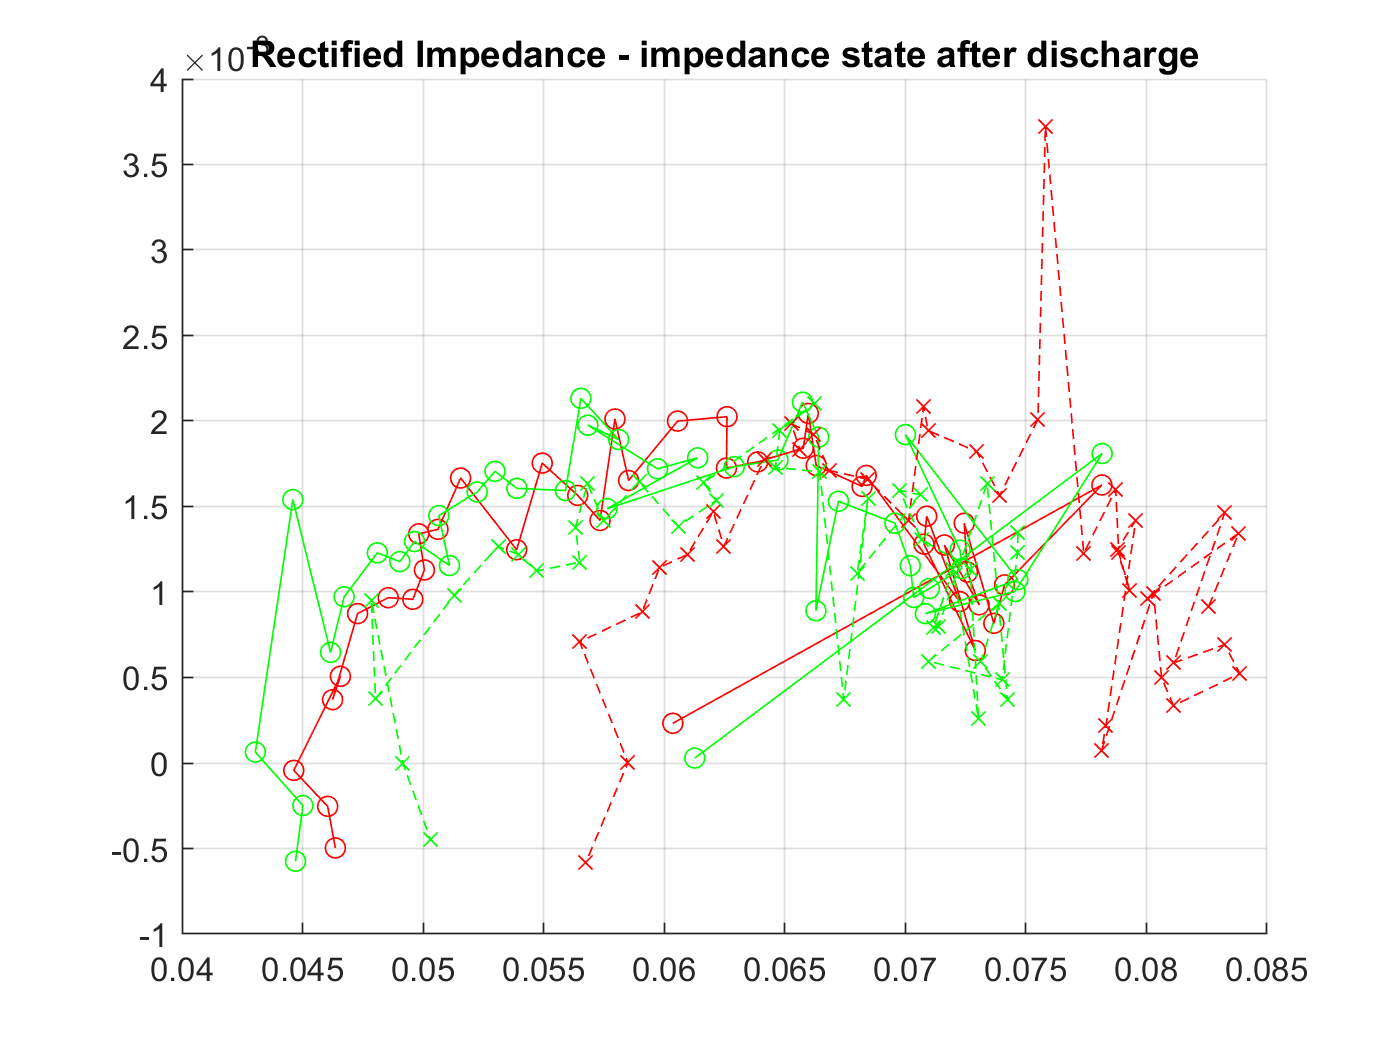


figure 
hold on
% after didscahage 43 47 
plot(BAT1.cycle(43).data.Rectified_Impedance','r-o')
plot(BAT1.cycle(47).data.Rectified_Impedance','g-o')
plot(BAT1.cycle(609).data.Rectified_Impedance','r--x')
plot(BAT1.cycle(615).data.Rectified_Impedance','g--x')
hold off
title("Rectified Impedance - impedance state after discharge")
grid on







figure
%newcolors = {'#F00','#F80','#FF0','#0B0','#00F','#50F','#A0F'};
%colororder(newcolors)

hold on
items = size(BAT1.cycle,2)

items =    616


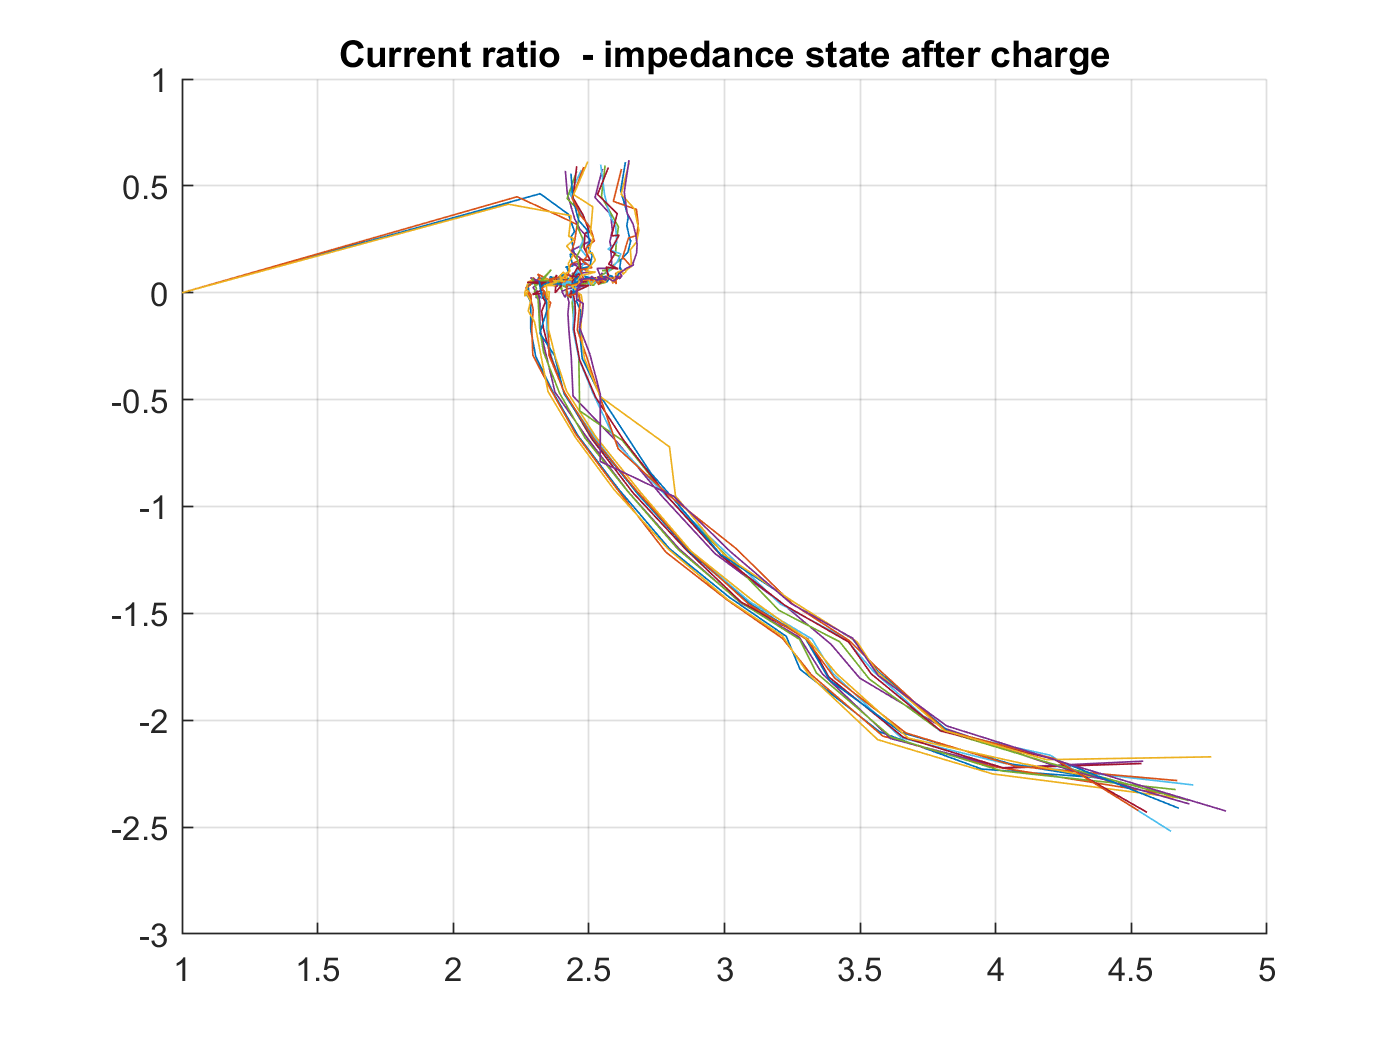

%marker = ['-','--',':','-.','-o','--o',':o','-.o','+',"*"]

line_stype = ['-','--',':', '-.'];
k=1;
for i=1:items
    if isequal(BAT1.cycle(i).type, 'impedance')
        if isequal(BAT1.cycle(i-1).type, 'charge')
            if mod(i , 10 ) == 1
                 
                %plot(BAT1.cycle(i).data.Time/60,BAT1.cycle(i).data.Current_ratio)
                plot(BAT1.cycle(i).data.Current_ratio,line_stype(k),'MarkerIndices',[1 2 3])
                k = k+1;
                if k == 4 
                    k =1;
                end
                
            end
        end
    end
end
hold off 
title("Current ratio  - impedance state after charge")
grid on

figure
%newcolors = {'#F00','#F80','#FF0','#0B0','#00F','#50F','#A0F'};
%colororder(newcolors)

hold on
items = size(BAT1.cycle,2)

items =    616


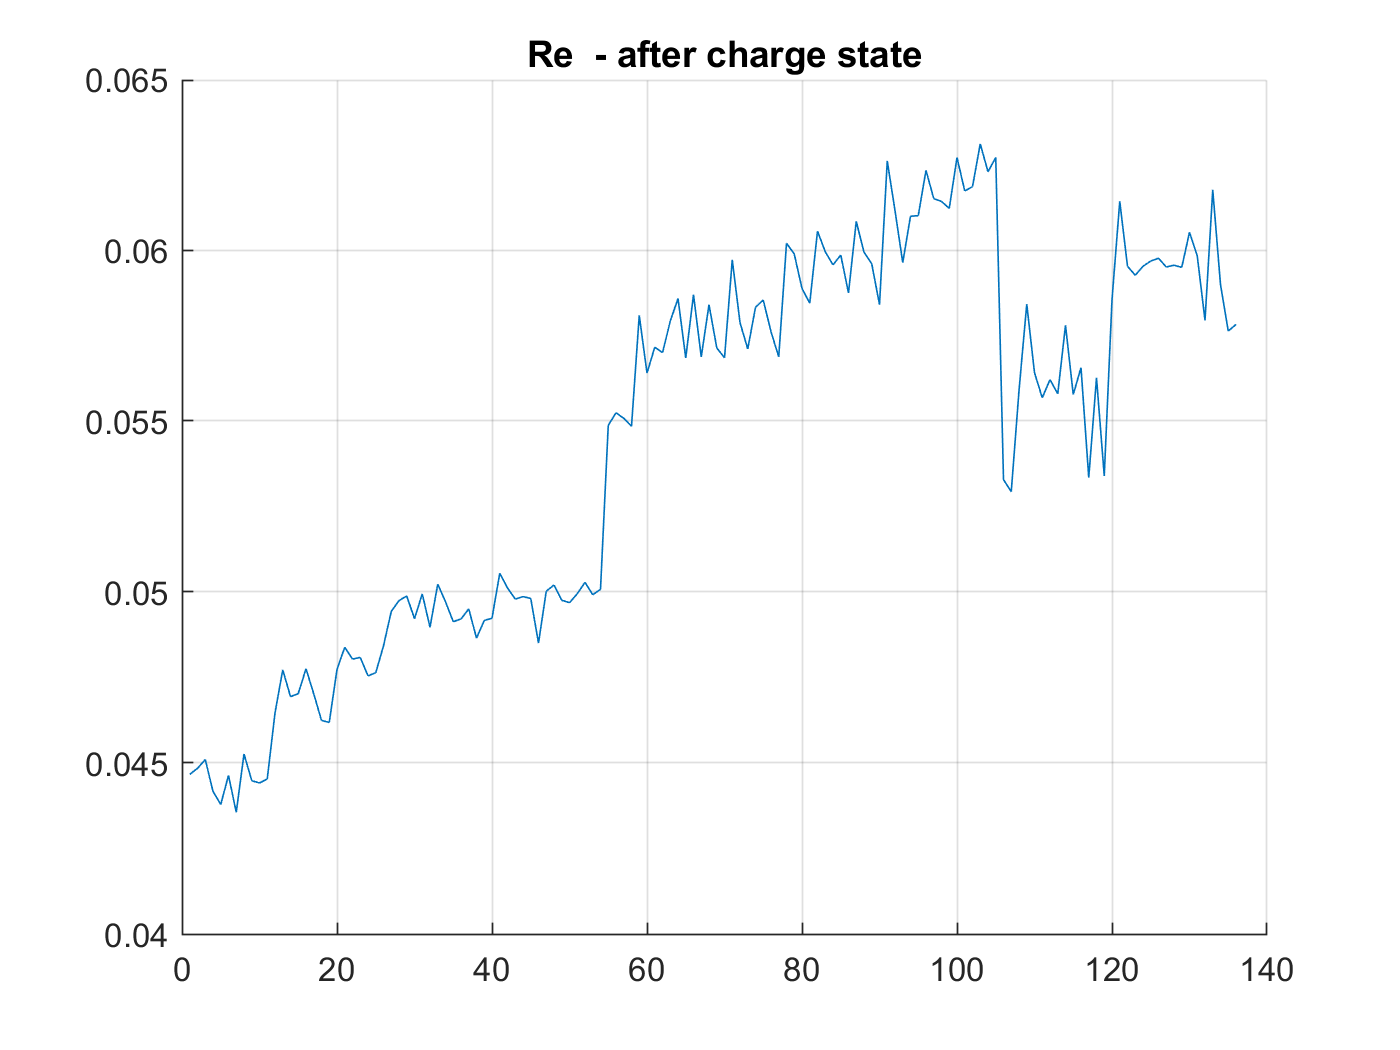

%marker = ['-','--',':','-.','-o','--o',':o','-.o','+',"*"]
Re_table = [];
Rct_table = [];
Time_table = [];
for i=1:items
    if isequal(BAT1.cycle(i).type, 'impedance')
         if isequal(BAT1.cycle(i-1).type, 'charge')
             Re_table = [Re_table, BAT1.cycle(i).data.Re ];
             Rct_table = [Rct_table, BAT1.cycle(i).data.Rct ];
             Time_table = [Time_table ,BAT1.cycle(i).time ];
            %if mod(i , 10 ) == 1
            %    k = mod (round(i / 10), 10 ) + 1;
            %    plot(BAT1.cycle(i).data.Re)
            %end
         end
    end
end
plot(Re_table)

hold off 
title("Re  - after charge state")
grid on

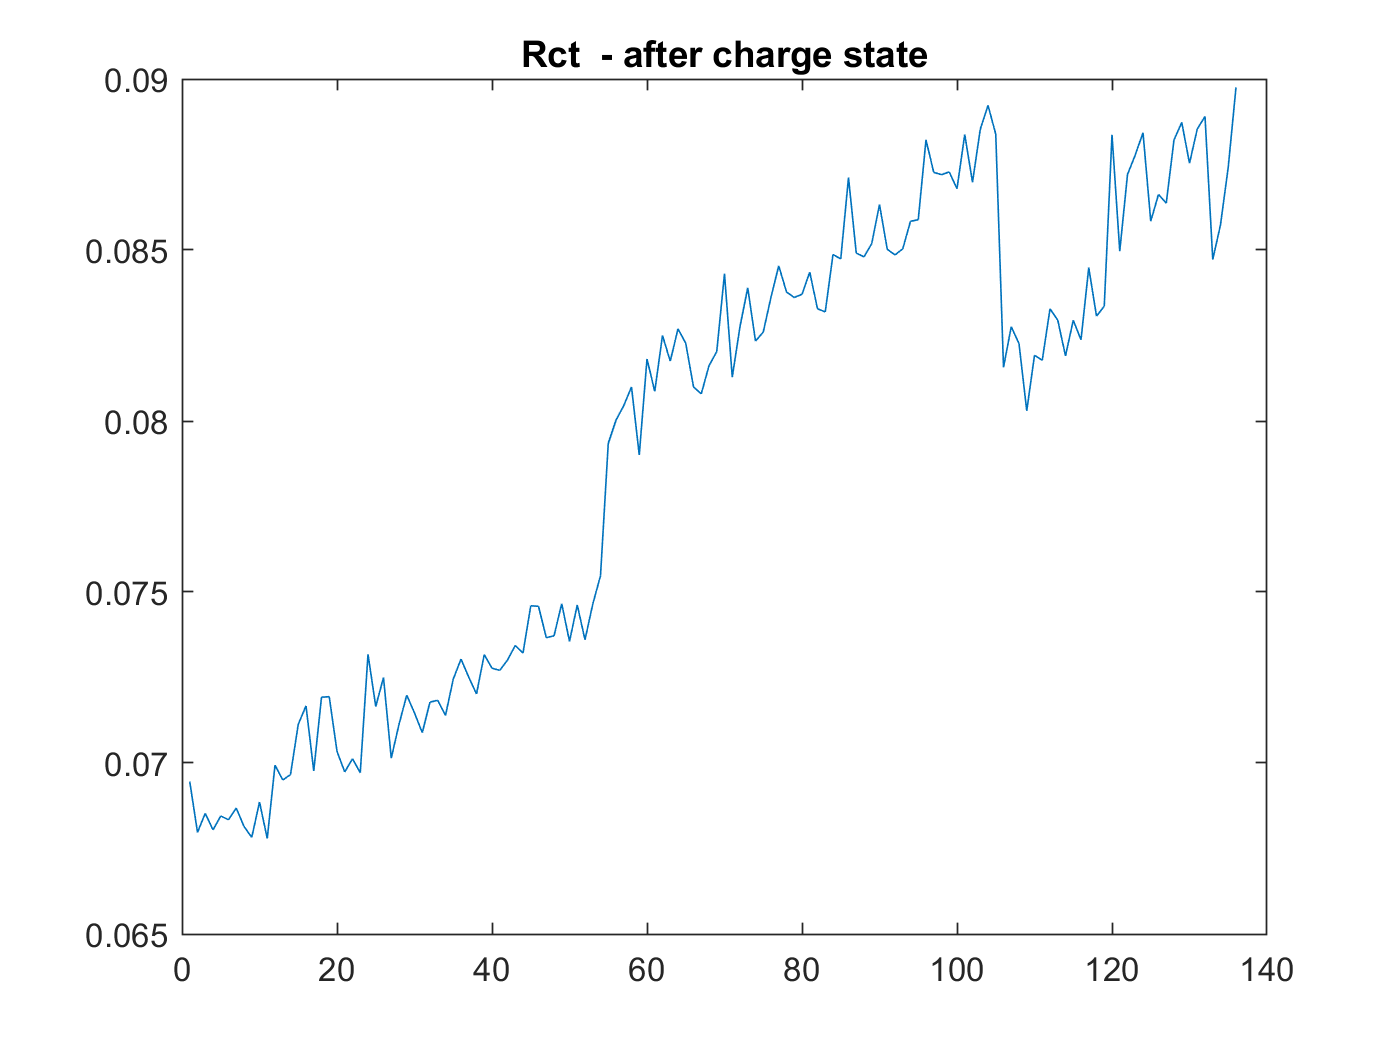

%figure
%plot(Time_table,Re_table)


figure 
plot(Rct_table)

title("Rct  - after charge state")




%%%
%Charging 
%constant current (CC) mode at 1.5A until the battery voltage reached 4.2V 
%constant voltage (CV) mode until the charge current dropped to 20mA. 

%Voltage_measured: Battery terminal voltage (Volts)
%Current_measured: Battery output current (Amps)
%Temperature_measured: Battery temperature (degree C)
%Current_charge: Current measured at charger (Amps)
%Voltage_charge: Voltage measured at charger (Volts)
%Time: Time vector for the cycle (secs)
%%%







%%%%%% Registor 



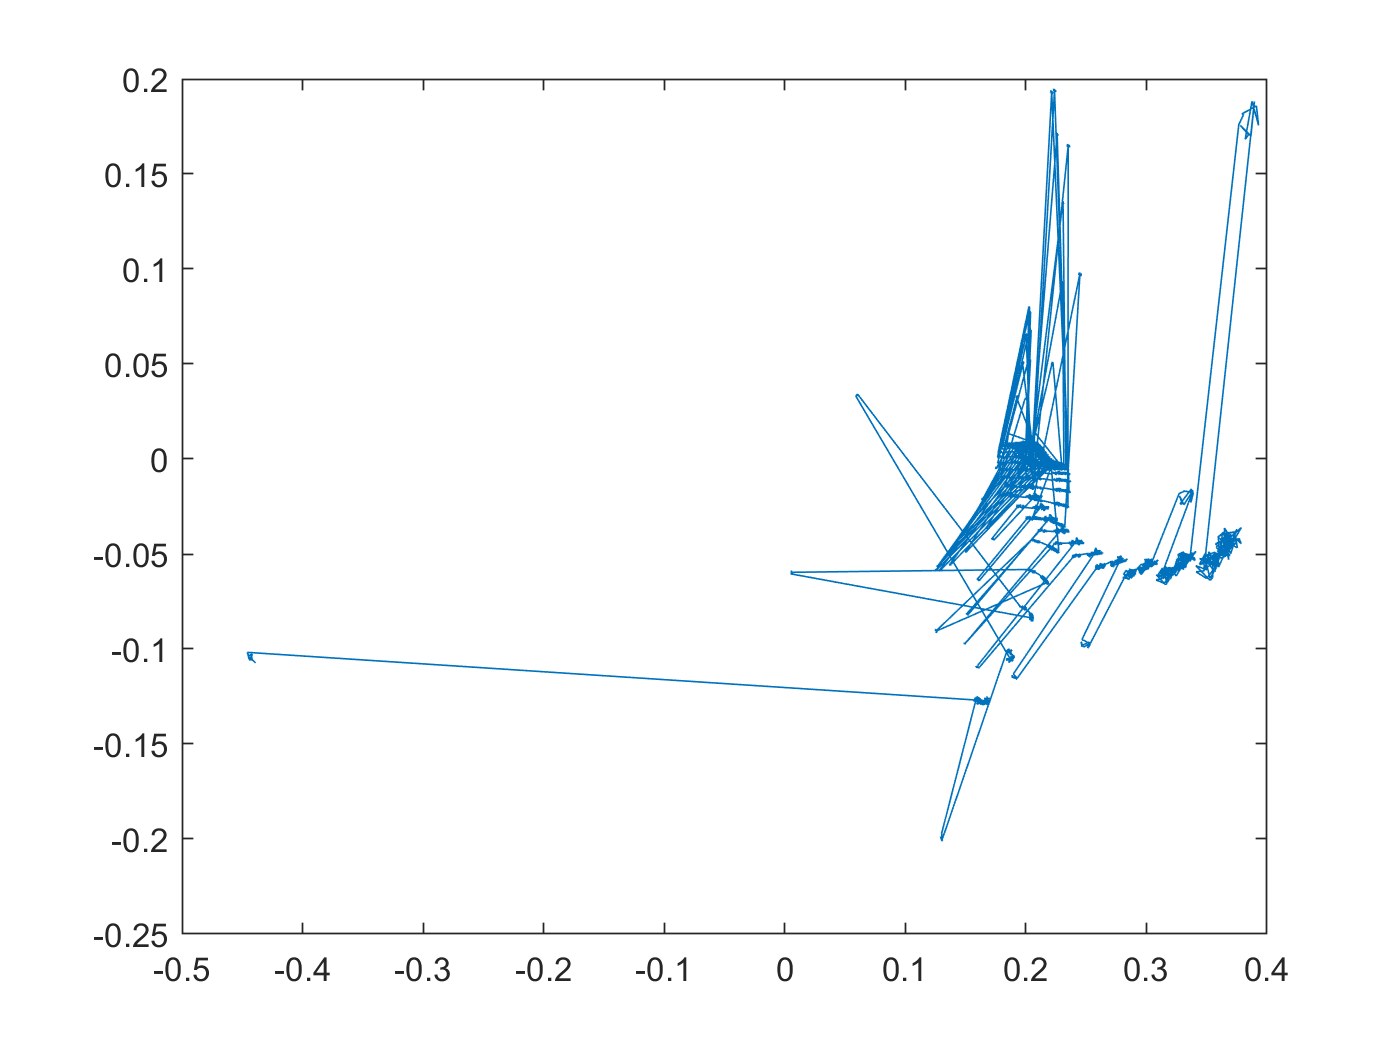

%%%%%%% Impedance

% find first Battery_impedance
imp = [];
for i = 1:length(BAT1.cycle)
    if isequal(BAT1.cycle(i).type, 'impedance')
        if isequal(BAT1.cycle(i-1).type, 'charge')
            imp(i,:) = BAT1.cycle(i).data.Battery_impedance;
            imp_rect(i,:) = transpose( BAT1.cycle(i).data.Rectified_Impedance);
        end
    end
end
imp(imp==0) = [];
imp_rect(imp_rect==0) = [];


figure
plot(imp) 

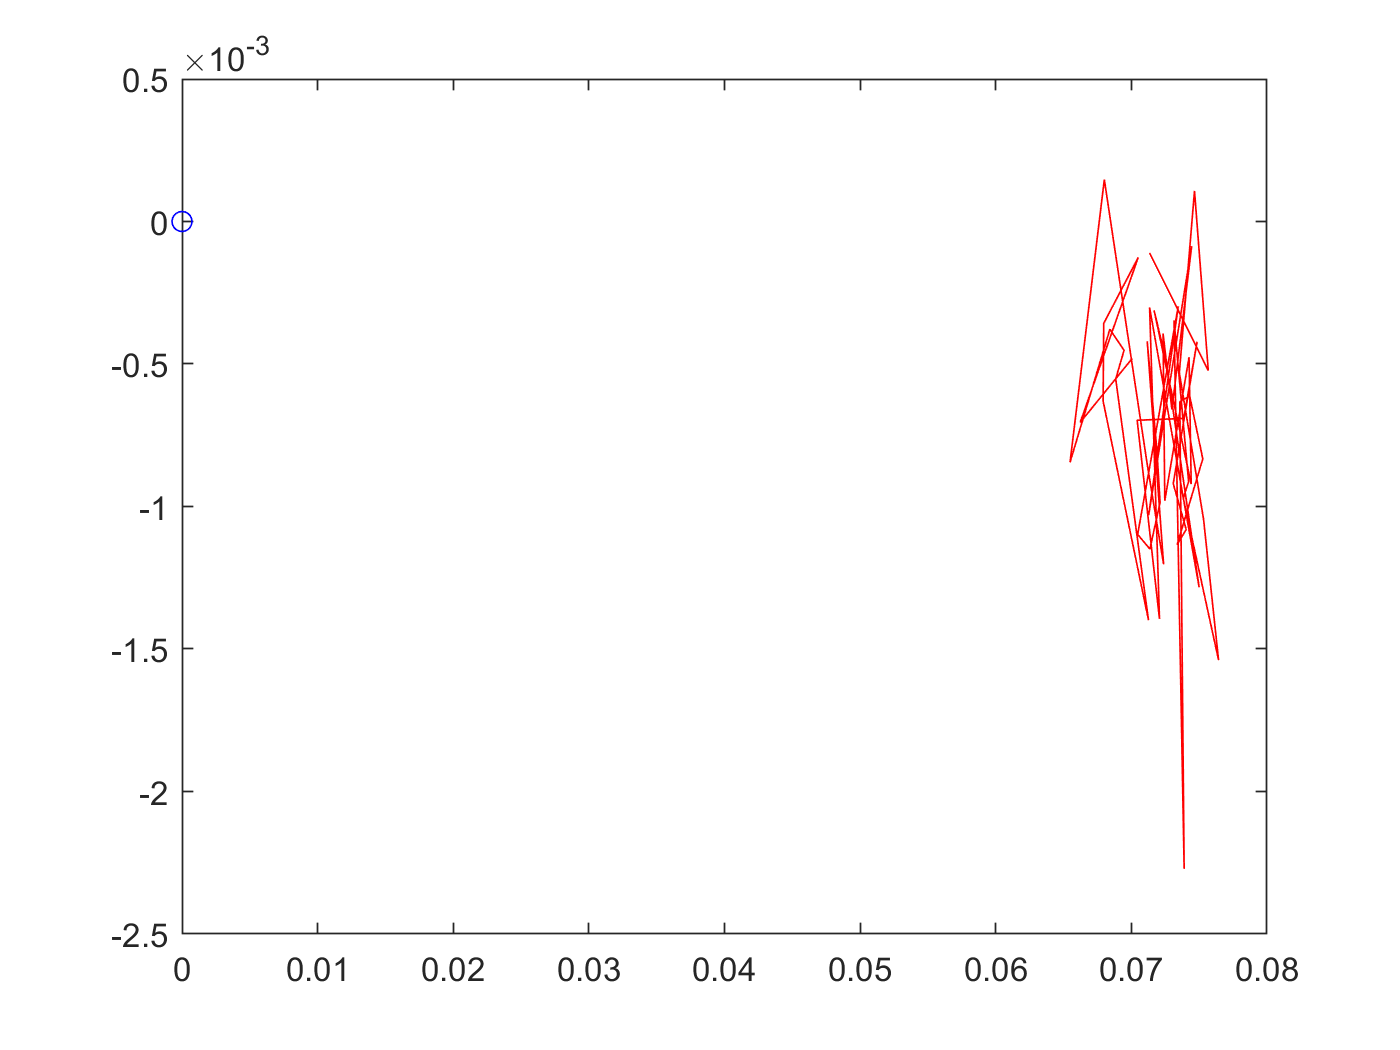

figure
plot(0,0,'bo',real(imp_rect(1:50)),imag(imp_rect(1:50)),'r')

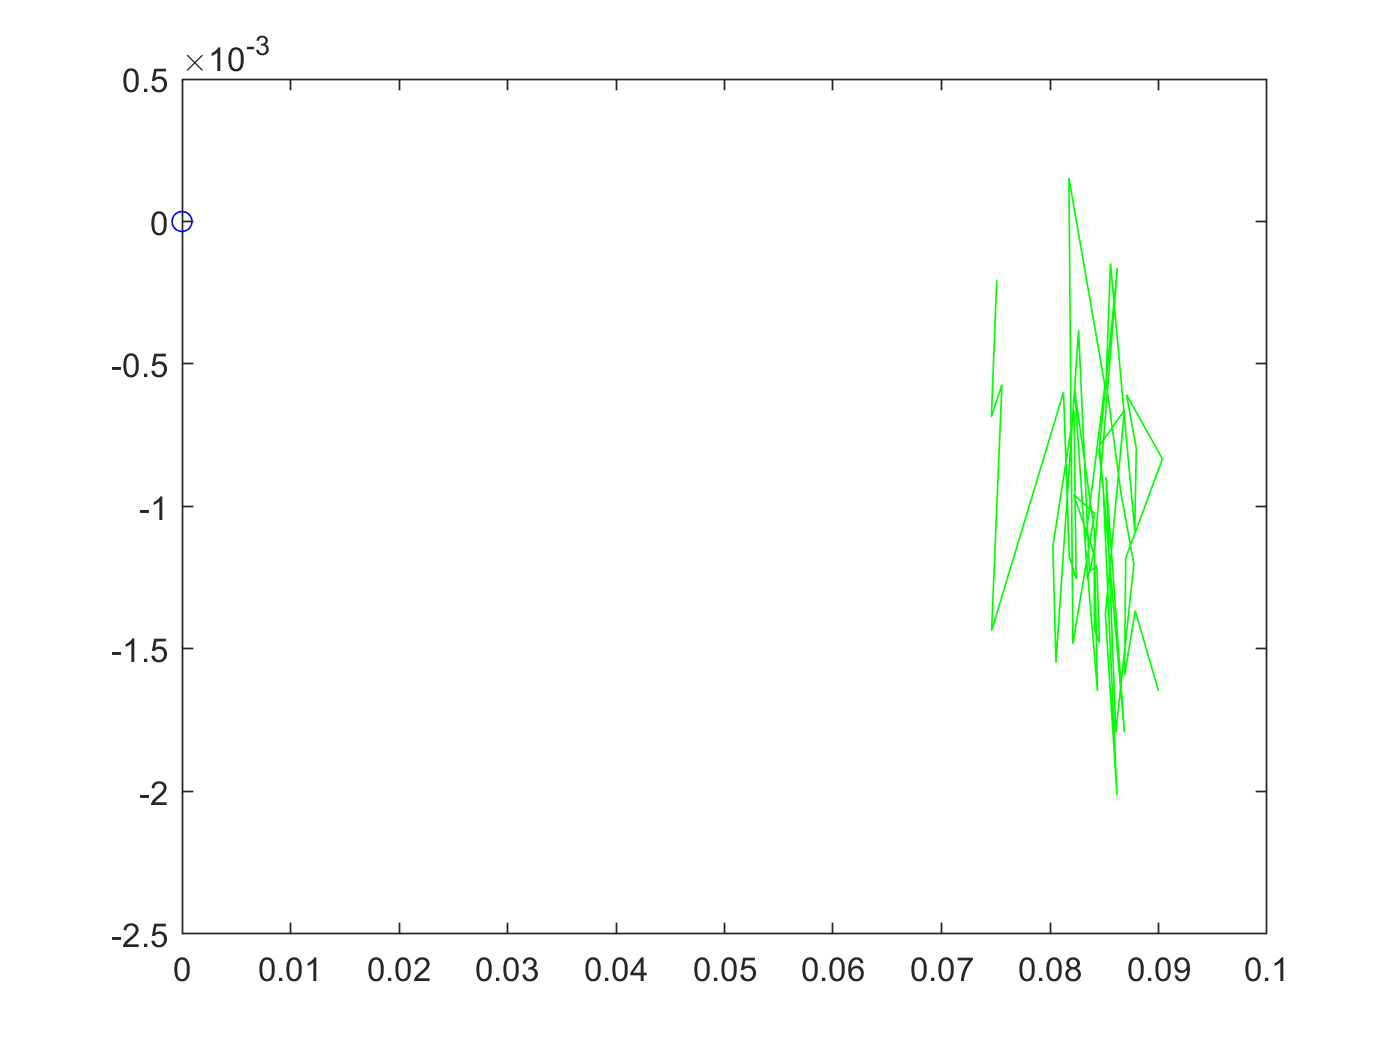

figure
plot(0,0,'bo',real(imp_rect(51:100)),imag(imp_rect(51:100)),'g')

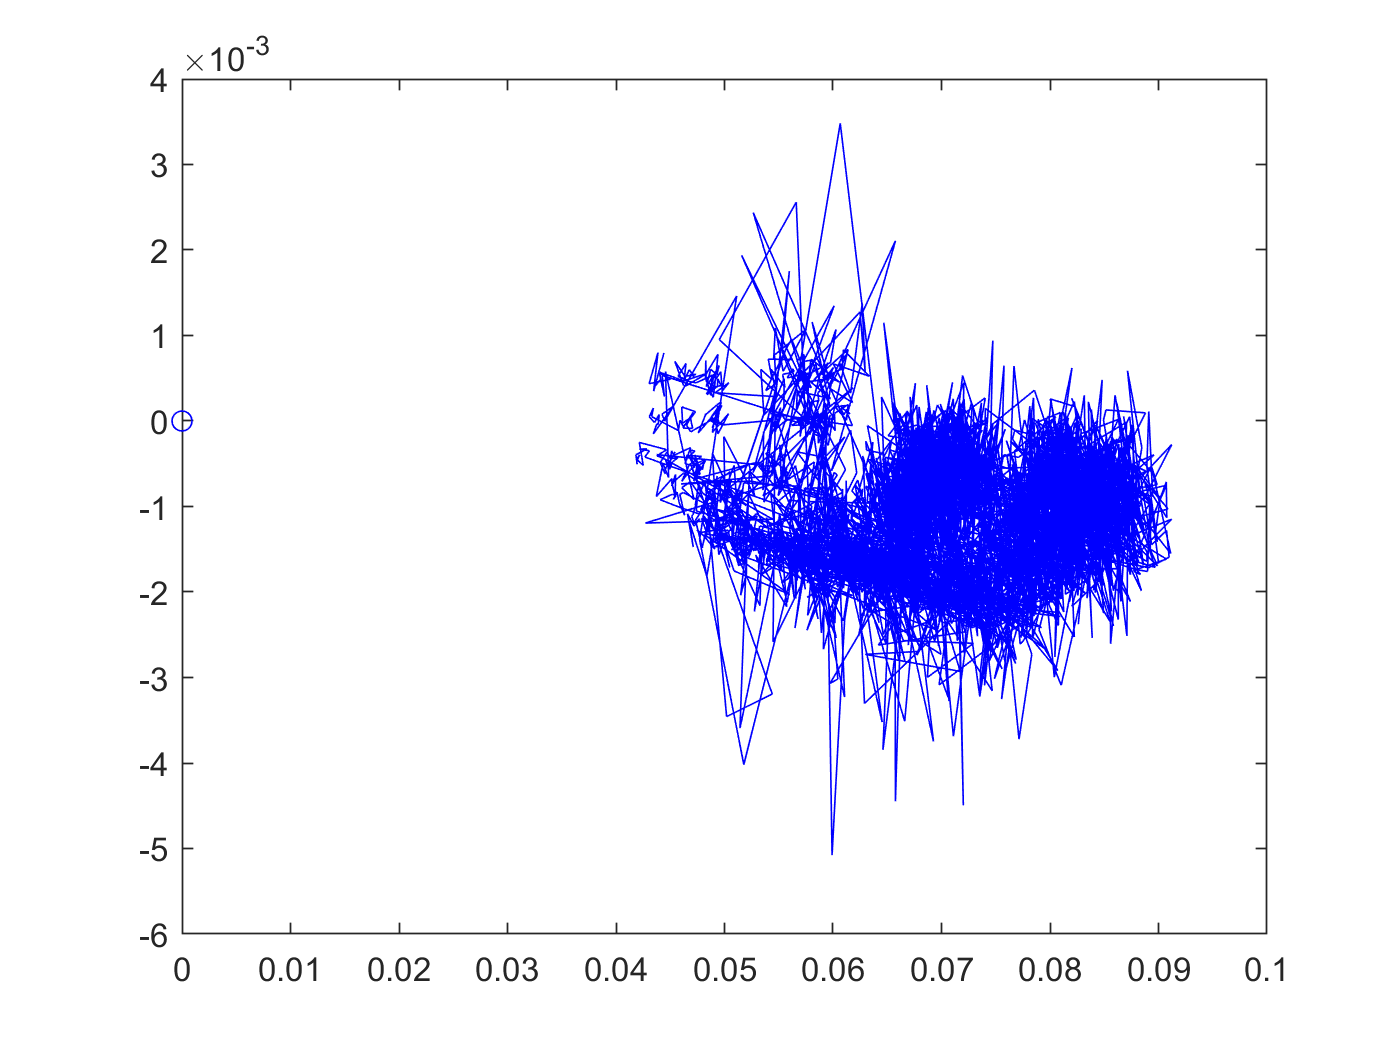

figure
plot(0,0,'bo',real(imp_rect(100:end)),imag(imp_rect(100:end)),'b')

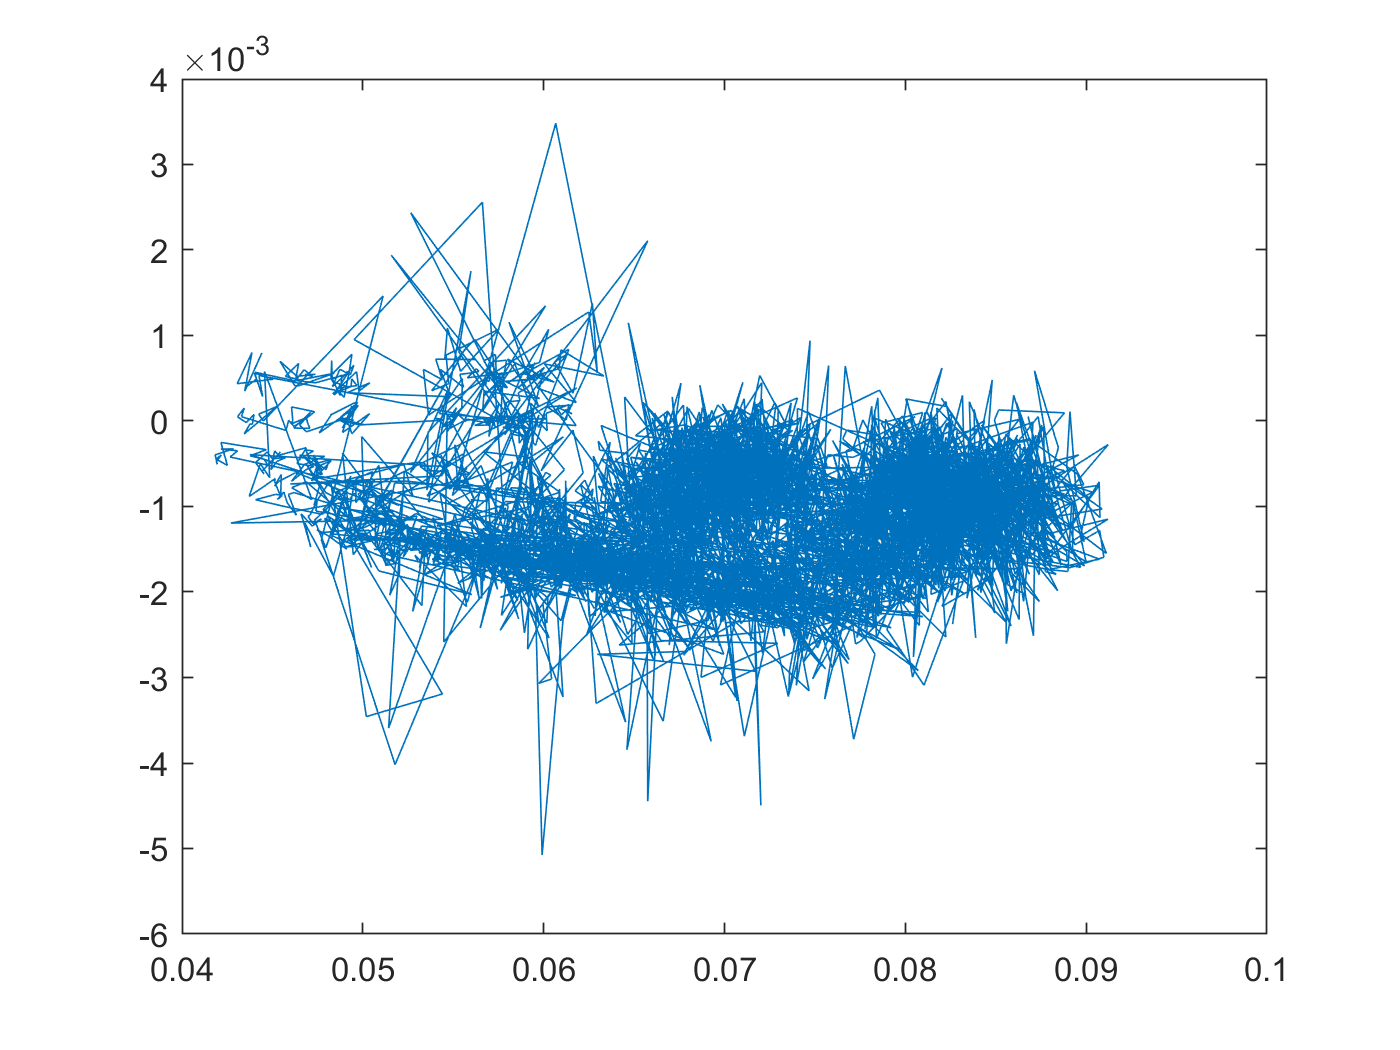


%axis([-0.01 0.1 -0.02 0.02])
%colormap(ax2,jet)
%axis square

figure
plot(imp_rect)

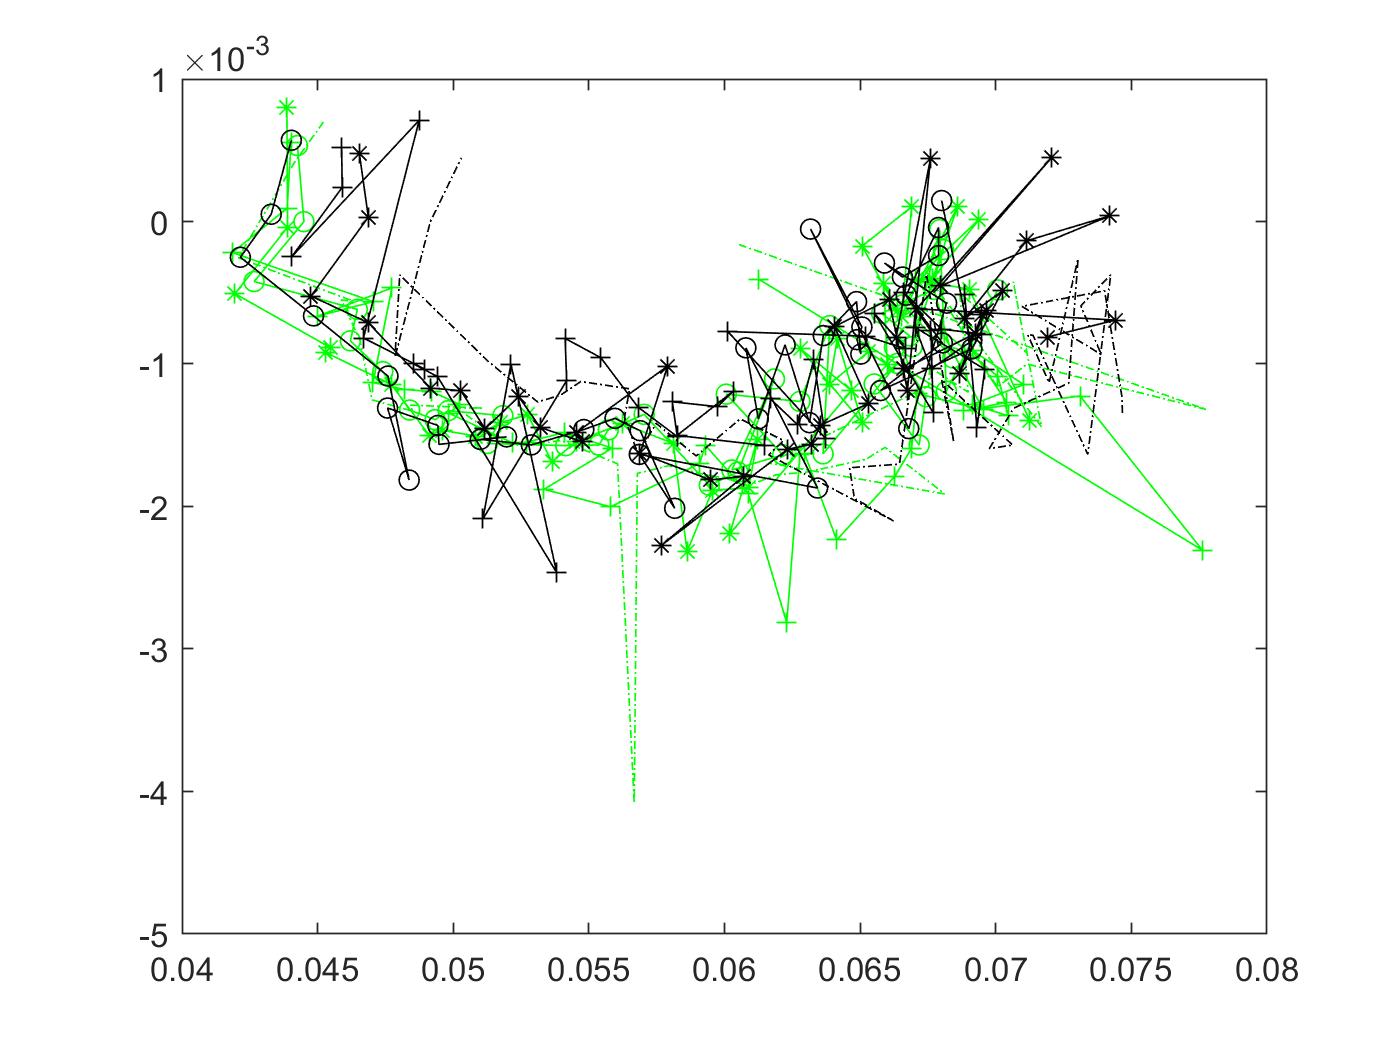



data = BAT1.cycle(41).data.Battery_impedance;
data1 = BAT1.cycle(51).data.Battery_impedance;
data2 = BAT1.cycle(61).data.Battery_impedance;
data3 = BAT1.cycle(71).data.Battery_impedance;
data4 = BAT1.cycle(81).data.Battery_impedance;
data5 = BAT1.cycle(91).data.Battery_impedance;
data6 = BAT1.cycle(101).data.Battery_impedance;
data7 = BAT1.cycle(615).data.Battery_impedance;

rdata = BAT1.cycle(41).data.Rectified_Impedance;
rdata1 = BAT1.cycle(51).data.Rectified_Impedance;
rdata2 = BAT1.cycle(61).data.Rectified_Impedance;
rdata3 = BAT1.cycle(71).data.Rectified_Impedance;
rdata4 = BAT1.cycle(81).data.Rectified_Impedance;
rdata5 = BAT1.cycle(91).data.Rectified_Impedance;
rdata6 = BAT1.cycle(101).data.Rectified_Impedance;
rdata7 = BAT1.cycle(615).data.Rectified_Impedance;

data_re = real(data);
data_im = imag(data);

figure
plot(rdata,'g-o') 
hold on, 
plot(rdata,'g-o'),plot(rdata1,'g-+'), plot(rdata2,'g-*'),plot(rdata3,'g-.'),
plot(rdata4,'k-o'),plot(rdata5,'k-+'), plot(rdata6,'k-*'),plot(rdata7,'k-.'),

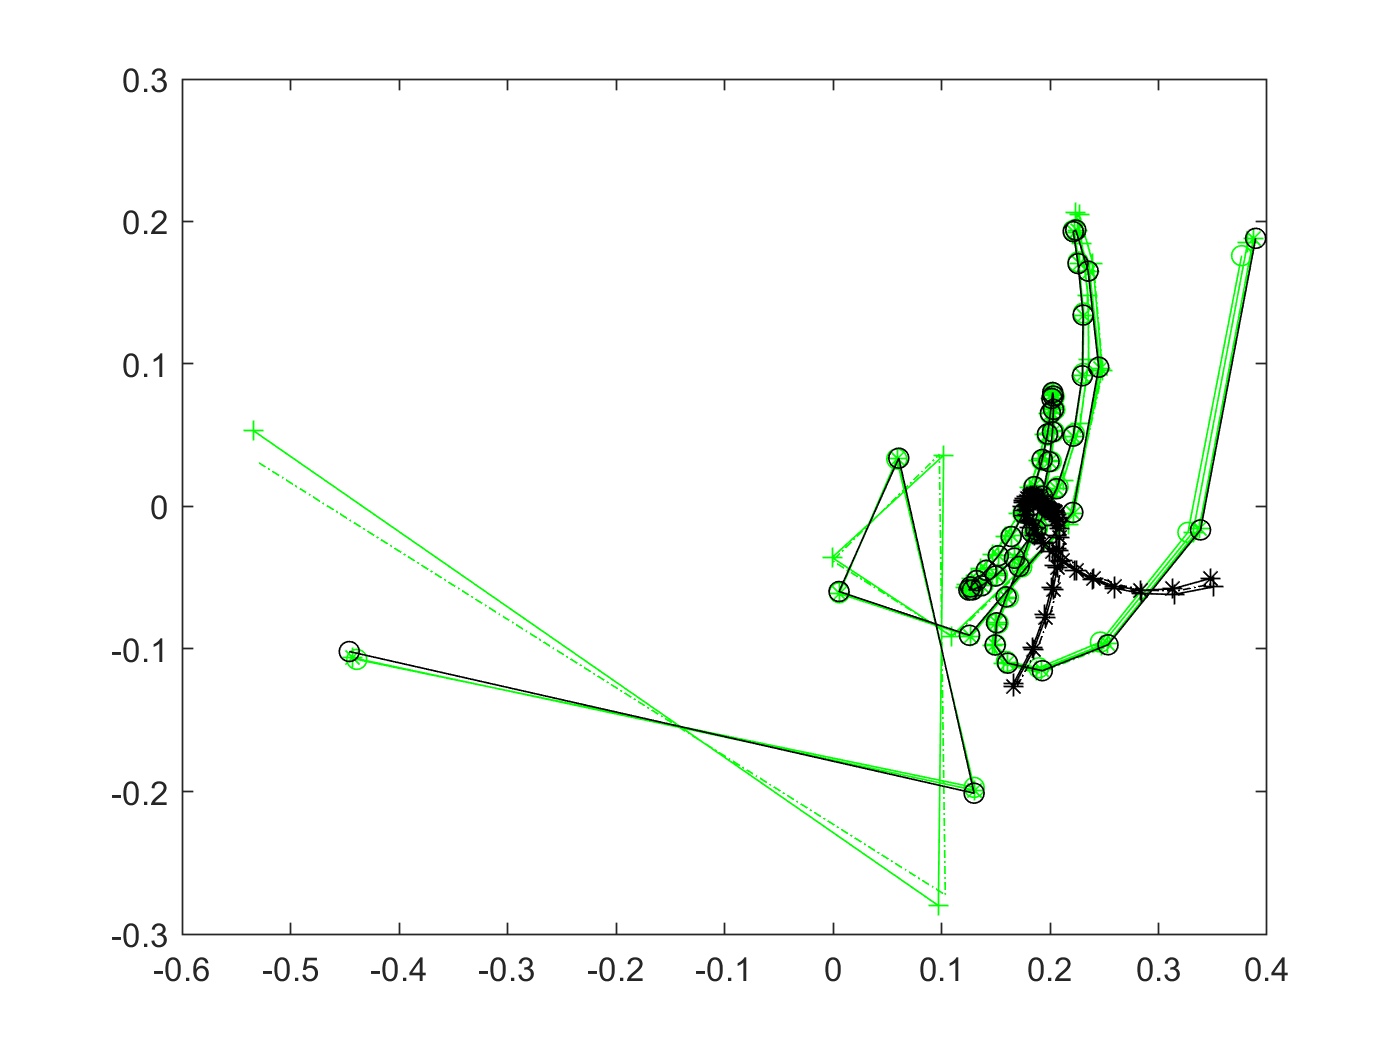


figure
plot(data,'g-o') 
hold on, 
plot(data,'g-o'),plot(data1,'g-+'), plot(data2,'g-*'),plot(data3,'g-.'),
plot(data4,'k-o'),plot(data5,'k-+'), plot(data6,'k-*'),plot(data7,'k-.'),